Setup

addpath(genpath(pwd))

%optional
set(0,'defaultTextInterpreter','none')
set(groot,'defaulttextinterpreter','none');
set(groot, 'DefaultAxesTickLabelInterpreter', 'none')
set(groot, 'defaultLegendInterpreter','none');

feature astheightlimit 2000

ans = 'feature astHeightLimit 500'

conditions= {'cancer', 'control'};
altcolor= [255 255 255;255 204 204; 255 153 153; 255 102 102; 255 51 51;...
    255 0 0; 204 0 0; 152 0 0; 102 0 0;  51 0 0]/255; %shorter 10% = 1 bar

delete clone*.log %delete some files generated by cplex

## 3.1 Expression data input

Import the gene expression data into Matlab. 

data_cancer = readtable('fpkm_BRCA_cancer.txt', "ReadRowNames",true);
data_control = readtable('fpkm_BRCA_control.txt', "ReadRowNames",true);
data = [data_cancer, data_control];

fpkm = table2array(data);
rownames = data.Properties.RowNames;
colnames = data.Properties.VariableNames;

discretization step 

% discretized = discretize_FPKM(fpkm, colnames,1) %for figures
discretized = discretize_FPKM(fpkm, colnames); % no figures

## 3.2. Context-specific model reconstruction

human reconstruction Recon 2.04 

can also be downloaded from https://www.vmh.life/files/reconstructions/Recon/2.04/Recon2.v04.mat_.zip. 

load Recon2.v04.mat

consitent model creation

A = fastcc_4_rfastcormics(modelR204, 1e-4,0);

Elapsed time is 162.815675 seconds.


consistent_model = removeRxns(modelR204, modelR204.rxns(setdiff(1:numel(modelR204.rxns),A)));

## Set a description

consistent_model.description= 'recon';
%fix rule
 consistent_model.rules(1903)={'(x(1039)) | (x(1040)) | (x(1041)) | (x(1042)) | (x(1043)) | (x(1044)) | (x(1045)) | (x(1046)) | (x(1047)) | (x(1048)) | (x(1049)) | (x(1050)) '};
% setting parameters

load medium_example.mat
load dico_ML.mat

epsilon = 1e-4;
consensus_proportion = 0.9;

already_mapped_tag = 0;
unpenalizedSystems = {'Transport, endoplasmic reticular';
    'Transport, extracellular';
    'Transport, golgi apparatus';
    'Transport, mitochondrial';
    'Transport, peroxisomal';
    'Transport, lysosomal';
    'Transport, nuclear'};
unpenalized = consistent_model.rxns(ismember(consistent_model.subSystems,unpenalizedSystems));
optional_settings.unpenalized = unpenalized;

optional_settings.func = {'DM_atp_c_'}; % forced reactions

not_medium_constrained = 'EX_tag_hs(e)';% if no constrain is used please remove the field.
optional_settings.not_medium_constrained = not_medium_constrained;

optional_settings.medium = medium_example;% if no medium is used please remove the field.

biomass_rxn = {'biomass_reaction'};

reconstruct the context-specific models

consensus models

**Only use the index for structure analysis !**

[model_cancer, A_final_cancer] = fastcormics_RNAseq(consistent_model, discretized(:,1:10), rownames, dico, biomass_rxn, already_mapped_tag, consensus_proportion, epsilon, optional_settings);

2047 of 2140 genes matched
Warning metaboltes with X in their Formulas these inputs are closed
Warning metaboltes with Y in their Formulas these inputs are closed
Elapsed time is 28.810642 seconds.


[model_control, A_final_control] = fastcormics_RNAseq(consistent_model, discretized(:,11:20), rownames, dico, biomass_rxn, already_mapped_tag, consensus_proportion, epsilon, optional_settings);

2047 of 2140 genes matched
Warning metaboltes with X in their Formulas these inputs are closed
Warning metaboltes with Y in their Formulas these inputs are closed
Elapsed time is 33.042211 seconds.


models_keep_consensus=zeros(numel(consistent_model.rxns),numel(conditions));
name=strcat('ConsensusModel_','model_cancer');
save (name, 'model_cancer');
name=strcat('ConsensusModel_','model_control');
save (name, 'model_control');

sample-specific models

models_keep = zeros(numel(consistent_model.rxns), numel(colnames));

for i = 1:numel(colnames) %for each sample
    [ContextModel, A_keep] = fastcormics_RNAseq(consistent_model, discretized(:,i), ...
        rownames, dico, biomass_rxn, already_mapped_tag, consensus_proportion, epsilon, optional_settings);
     name=strcat('SampleModel_',colnames{i});
        save (name, 'ContextModel');   
        models_keep(A_keep,i) = 1;
end

2047 of 2140 genes matched
Warning metaboltes with X in their Formulas these inputs are closed
Warning metaboltes with Y in their Formulas these inputs are closed
Elapsed time is 49.901499 seconds.
2047 of 2140 genes matched
Warning metaboltes with X in their Formulas these inputs are closed
Warning metaboltes with Y in their Formulas these inputs are closed
Elapsed time is 52.639049 seconds.
2047 of 2140 genes matched
Warning metaboltes with X in their Formulas these inputs are closed
Warning metaboltes with Y in their Formulas these inputs are closed
Elapsed time is 36.673455 seconds.
2047 of 2140 genes matched
Warning metaboltes with X in their Formulas these inputs are closed
Warning metaboltes with Y in their Formulas these inputs are closed
Elapsed time is 34.393683 seconds.
2047 of 2140 genes matched
Warning metaboltes with X in their Formulas these inputs are closed
Warning metaboltes with Y in their Formulas these inputs are closed
Elapsed time is 41.435093 seconds.
2047 of 21

## 3.3. Basic model and pathway analysis

similarity between two models can be assessed via the Jaccard similarity index

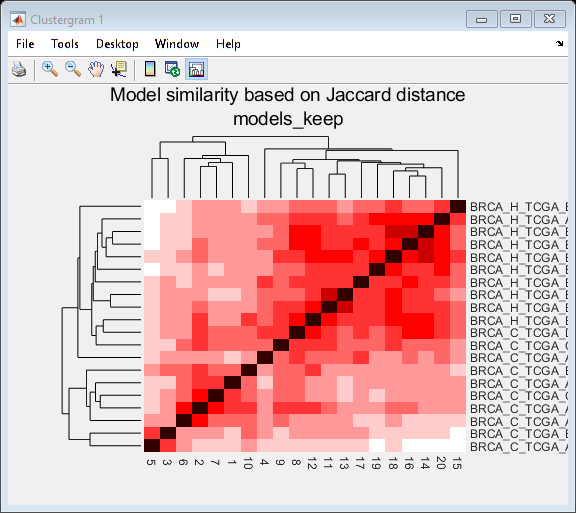

J = squareform(pdist(models_keep','jaccard'));

cgo_J = clustergram(1-J,...
    'RowLabels', colnames,...
    'ColumnLabels', [],...
    'ColumnLabelsRotate',270, ...
    'Cluster', 'all', ...
    'symmetric','False',...
    'Colormap', altcolor);
addTitle(cgo_J,{'Model similarity based on Jaccard distance','models_keep'});

Pathway analysis 

Pathways = table(unique(consistent_model.subSystems));
[pathways, ~, ub] = unique(consistent_model.subSystems);
path_counts = histc(ub, 1:length(pathways));
T = table(pathways, path_counts);
[~, ia, ib] = intersect(Pathways.Var1, T.pathways);
Pathways.consistent(ia) = T.path_counts(ib);

pathway information for the consensus models

[pathways, ~, ub] = unique(consistent_model.subSystems(models_keep_consensus(:,1)~=0));
path_counts = histc(ub, 1:length(pathways));
T = table(pathways, path_counts);
[~, ia, ib] = intersect(Pathways.Var1, T.pathways);
Pathways.Var2(ia) = T.path_counts(ib) ;
Pathways.Properties.VariableNames{3} = 'cancer_consensus';

[pathways, ~, ub] = unique(consistent_model.subSystems(models_keep_consensus(:,2)~=0));
path_counts = histc(ub, 1:length(pathways));
T = table(pathways, path_counts);
[~, ia, ib] = intersect(Pathways.Var1, T.pathways);
Pathways.Var2(ia) = T.path_counts(ib) ;
Pathways.Properties.VariableNames{4} = 'control_consensus';

pathway information for the sample-specific models

for i=1:numel(colnames)
    [pathways, ~, ub] = unique(consistent_model.subSystems(models_keep(:,i)~=0));
    path_counts = histc(ub, 1:length(pathways));
    T = table(pathways, path_counts);
    [~, ia, ib] = intersect(Pathways.Var1, T.pathways);
    Pathways.Var2(ia) = T.path_counts(ib) ;
    Pathways.Properties.VariableNames{4+i} = colnames{i};
end

pathway activity rates

PathwayActivity = Pathways;
for i=3:size(PathwayActivity,2)
    PathwayActivity(:,i) = array2table(table2array(PathwayActivity(:,i))./table2array(PathwayActivity(:,2)));
end
disp(PathwayActivity)

                           Var1                            consistent    cancer_consensus    control_consensus    BRCA_C_TCGA_A8_A0AB_01A_11R_A034_07    BRCA_C_TCGA_AO_A12H_01A_11R_A115_07    BRCA_C_TCGA_E9_A1NC_01A_21R_A26B_07    BRCA_C_TCGA_A1_A0SM_01A_11R_A084_07    BRCA_C_TCGA_A2_A0D0_01A_11R_A00Z_07    BRCA_C_TCGA_A8_A06Y_01A_21R_A00Z_07    BRCA_C_TCGA_C8_A1HO_01A_11R_A13Q_07    BRCA_C_TCGA_D8_A4Z1_01A_21R_A266_07    BRCA_C_TCGA_C8_A1HL_01A_11R_A137_07    BRCA_C_TCGA_B6_A0RH_01A_21R_A115_07    BRCA_H_TCGA_BH_A1EO_11A_31R_A137_07    BRCA_H_TCGA_BH_A0DH_11A_31R_A089_07    BRCA_H_TCGA_BH_A204_11A_53R_A157_07    BRCA_H_TCGA_BH_A0BC_11A_22R_A089_07    BRCA_H_TCGA_BH_A1FG_11B_12

% comparison of 2 conditions
% pathways with a difference higher than 20% 

diff_idx = find(abs(table2array(PathwayActivity(:,3))- table2array(PathwayActivity(:,4))) > 0.2);

plotting

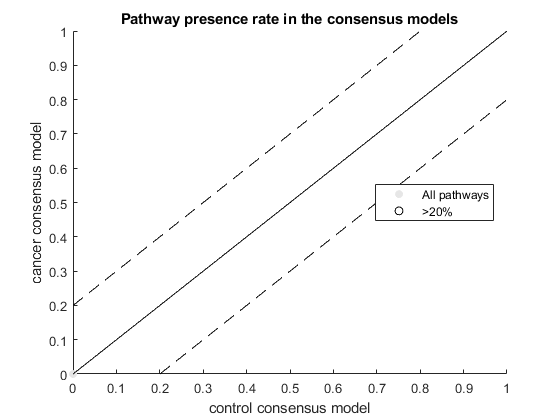

figure
hold on
scatter(table2array(PathwayActivity(:,3)),table2array(PathwayActivity(:,4)),'filled',...
    'MarkerFaceColor',[0.9 0.9 0.9])
scatter(table2array(PathwayActivity(diff_idx,3)),table2array(PathwayActivity(diff_idx,4)),...
    'black')
ylabel('cancer consensus model')
xlabel('control consensus model')
title('Pathway presence rate in the consensus models')
line([0 1], [0,1],'Color','k')
line([0 0.8], [0.2,1],'Color','k','LineStyle','--')
line([0.2 1], [0,0.8],'Color','k','LineStyle','--')
legend({'All pathways','>20%'},"Location","best")

text(table2array(PathwayActivity(diff_idx,3)),table2array(PathwayActivity(diff_idx,4)), PathwayActivity.Var1(diff_idx))

comparison of multiple samples

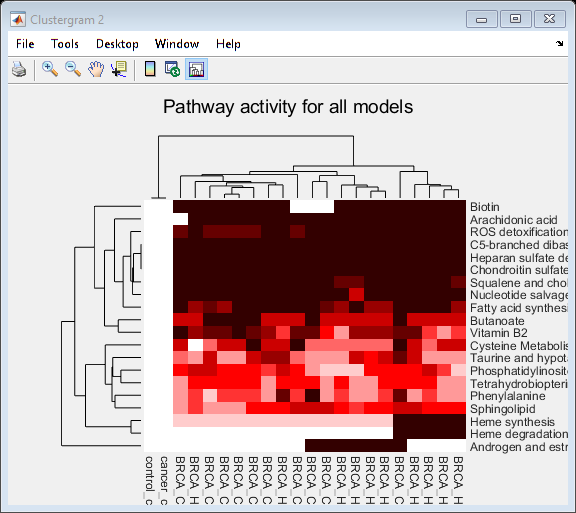

[~,I] = sort(sum(abs(table2array(PathwayActivity(:,3:end))-mean(table2array(PathwayActivity(:,3:end)),2)),2),'descend');



cgo = clustergram(table2array(PathwayActivity(I(1:20),3:end)),...
    'RowLabels', regexprep(PathwayActivity.Var1(I(1:20)),'metabolism',''),...
    'ColumnLabels', regexprep(PathwayActivity.Properties.VariableNames(3:end),'_TCGA.*',''),...
    'ColumnLabelsRotate',270, ...
    'Cluster', 'all', ...
    'symmetric','False',...
    'Colormap', altcolor);
addTitle(cgo,'Pathway activity for all models')

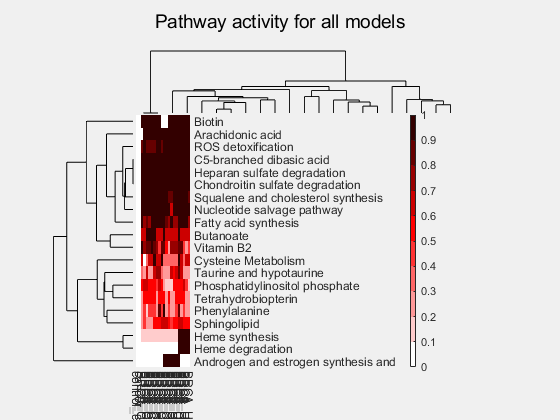

h = plot(cgo); set(h,'TickLabelInterpreter','none');
colorbar(h)

## 3.4. In silico gene deletion and drug repurposing

set the biomass reaction as objective function:

## perform the in silico gene deletion

initialize the solver

changeCobraSolver('ibm_cplex')


 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2019a.


ans = logical
   1


run the single gene deletion

  grRatio_biomass =zeros(numel(unique(strtok(consistent_model.genes)),'.'), numel(conditions));
  grRateKO_biomass =zeros(numel(unique(strtok(consistent_model.genes)),'.'), numel(conditions));
  grRateWT_biomass=zeros(numel(unique(strtok(consistent_model.genes)),'.'), numel(conditions));

geneList_keep=struct();
for i=1:numel(conditions) %for each model
    
    if i==1
    name=strcat('ConsensusModel_','model_cancer');
    else
     name=strcat('ConsensusModel_','model_control');

    end
    load(name)
     model_out=ContextModel;
    model_out = changeObjective(model_out,'DM_atp_c_');

    [grRatio_ATP, grRateKO_ATP, grRateWT_ATP, hasEffect, ~, ~, geneList] = singleGeneDeletion_rFASTCORMICS(model_out,'FBA',[],0,1);
    
   grRateWT_ATP=ones(numel(grRatio_ATP),1)*grRateWT_ATP;
    
    %Biomass
    
    model_out = changeObjective(model_out,'biomass_reaction');

     [grRatio_biomass, grRateKO_biomass, grRateWT_biomass, hasEffect, delRxns, fluxSolution, geneList] = singleGeneDeletion_rFASTCORMICS(model_out,'FBA',[],0,1);
       grRateWT_biomass=ones(numel(grRatio_biomass),1)*grRateWT_biomass;

     TEssential= table(geneList,grRatio_biomass,grRateKO_biomass, grRateWT_biomass,grRatio_ATP,grRateWT_ATP,grRateKO_ATP)
    name2= strcat('essential', conditions(i));
    save (name2{1},'TEssential');

end

grRateWT = 300.8428

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 2.8360

Single gene deletion analysis in progress ...
100%    [........................................]


TEssential = 1733×7 table
     geneList      grRatio_biomass    grRateKO_biomass    grRateWT_biomass    grRatio_ATP    grRateWT_ATP    grRateKO_ATP
    ___________    _______________    ________________    ________________    ___________    ____________    ____________

    '100'                 1                2.836               2.836               1            300.84          300.84   
    '10005'               1                2.836               2.836               1            300.84          300.84   
    '10007'               1                2.836               2.836               1            300.84          300.84   
    '100137049'           1                2.836               2.836               1            300.84          300.84   
   

grRateWT = 300.8428

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 2.8360

Single gene deletion analysis in progress ...
100%    [........................................]


TEssential = 1733×7 table
     geneList      grRatio_biomass    grRateKO_biomass    grRateWT_biomass    grRatio_ATP    grRateWT_ATP    grRateKO_ATP
    ___________    _______________    ________________    ________________    ___________    ____________    ____________

    '100'                 1                2.836               2.836               1            300.84          300.84   
    '10005'               1                2.836               2.836               1            300.84          300.84   
    '10007'               1                2.836               2.836               1            300.84          300.84   
    '100137049'           1                2.836               2.836               1            300.84          300.84   
   

## Drug deletion

define a list of drugs 

load GeneDrugRelations.mat
DrugList = unique(GeneDrugRelations.DrugName);
Drug_grRatio_ATP =zeros(numel(DrugList), numel(conditions));
Drug_grRateKO_ATP =zeros(numel(DrugList), numel(conditions));
Drug_grRateWT_ATP =zeros(numel(DrugList), numel(conditions));


Drug_grRatio_biomass =zeros(numel(DrugList), numel(conditions));
Drug_grRateKO_biomass =zeros(numel(DrugList), numel(conditions));
Drug_grRateWT_biomass =zeros(numel(DrugList), numel(conditions));

model_name={'model_cancer', 'model_control'};
for i=1:numel(conditions)
    name=strcat('ConsensusModel_',model_name{i});
    load(name);
    %ATP
    ind = find(~cellfun(@isempty, regexp(consistent_model.rxns, 'DM_atp_c_')));
    model_out=ContextModel;
    model_out = changeObjective(model_out,'DM_atp_c_');

    [grRatio, grRateKO, grRateWT] = DrugDeletion(model_out,'FBA',DrugList);
    
    Drug_grRatio_ATP(:,i)    = grRatio;
    Drug_grRateKO_ATP(:,i)   = grRateKO;
    Drug_grRateWT_ATP(:,i)   = grRateWT;
    
    %Biomass
     model_out = changeObjective(model_out,'biomass_reaction');

    
    [grRatio, grRateKO, grRateWT] =  DrugDeletion(model_out,'FBA',DrugList);
    
    Drug_grRatio_biomass(:,i)    = grRatio;
    Drug_grRateKO_biomass(:,i)   = grRateKO;
    Drug_grRateWT_biomass(:,i)   = grRateWT;
    
end

grRateWT = 300.8428

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 2.8360

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 300.8428

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 2.8360

Single gene deletion analysis in progress ...
100%    [........................................]


## cancer-specific drugs for repurposing

cancer_drugs = DrugList(sum(Drug_grRatio_biomass(:,1) < 0.5));
control_drugs = DrugList(sum(Drug_grRatio_ATP(:,2) < 0.9));

cancer_specific_drugs = setdiff(cancer_drugs, control_drugs);